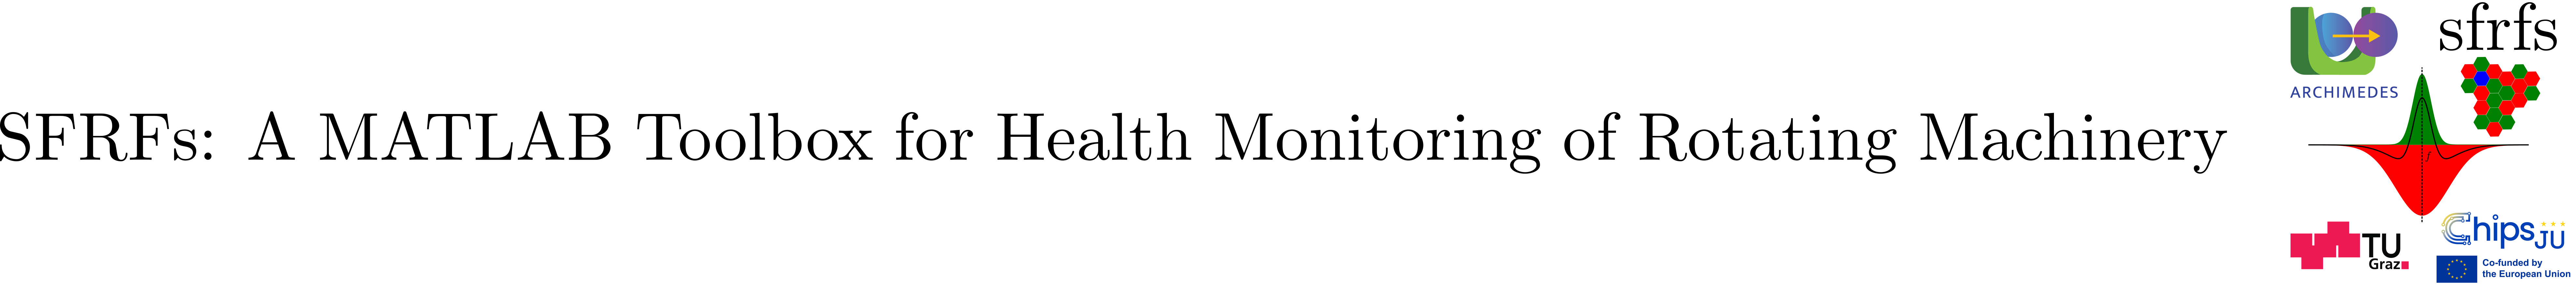

# MaskParameters

## Summary

MaskParameters defines the abstract base class for frequency-mask parameter objects used in the SFRFs perceptual pipeline.

## Description

MaskParameters provides a common abstraction for parameter objects that configure frequency-domain masks independently of their evaluation. It establishes a uniform interface for representing mask configuration while delegating the actual construction of frequency masks to `FrequencyMask.evaluate`.

Concrete subclasses such as [`GaussianMaskParameters`](matlab:open('./GaussianMaskParameters.mlx')) and [`SuperGaussianMaskParameters`](matlab:open('./SuperGaussianMaskParameters.mlx')) encode mask-specific parameters and validation rules, enabling mask generation to be dispatched based on parameter type. This design decouples mask specification from mask computation and allows new mask types to be introduced without modifying downstream processing logic. Figure 1. depicts the inheritance relation and corresponding parameterizations.

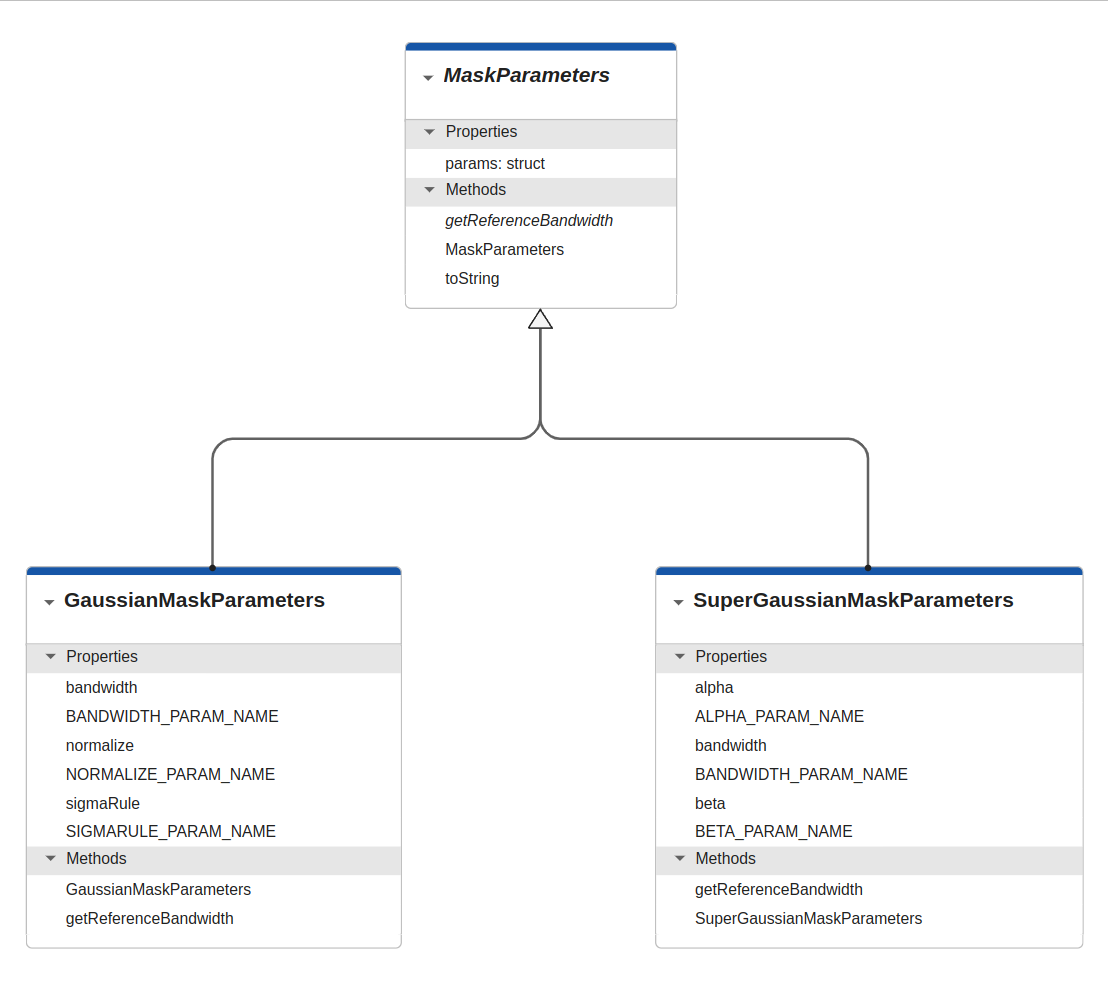

Figure 1. Gaussian and super-Gaussian parameterizations.

### Properties

The `params` property provides a uniform access point for parameter values associated with a given mask type. Its structure and contents are defined by the corresponding subclass and are interpreted downstream by `FrequencyMask.evaluate`. `MaskParameters` itself does not impose any constraints on the fields stored in `params` beyond serving as a common structural convention.

### Abstract methods

#### `getReferenceBandwidth`

Return a reference bandwidth, in Hz, associated with the mask parameterization. This method defines the canonical bandwidth implied by a concrete `MaskParameters` subclass and is used during band construction and validation.

Subclasses must implement this method to expose the bandwidth scale inherent to their parameterization. No assumptions are made at this level about how the bandwidth is derived or how it is subsequently used.

#### Syntax (by example)

- bw = params.getReferenceBandwidth();

**Outputs**

- `bw` (double scalar) - Reference bandwidth in Hz implied by the mask parameterization.

### Notes

- MaskParameters is intended to be subclassed and is not used directly.

- Subclasses are consumed by `FrequencyMask.evaluate` to generate frequency masks in a unified and extensible manner.

- This class provides the architectural anchor for parameter-object-based mask evaluation and does not replace legacy, function-based mask generation methods.

### See also

[FrequencyMask](matlab:open('./FrequencyMask.mlx')), [GaussianMaskParameters](matlab:open('./GaussianMaskParameters.mlx')), [SuperGaussianMaskParameters](matlab:open('./SuperGaussianMaskParameters.mlx'))

## API documentation

### MATLAB help

help MaskParameters

  MaskParameters
 
  Abstract base class for mask profile parameterization.
 
  The semantic meaning of a mask is defined by the concrete subclass
  (e.g. GaussianMaskParameters, SuperGaussianMaskParameters).
 
  Parameters are stored as a dictionary (actually a struct) to accommodate
  instance-specific naming.

    Documentation for MaskParameters



## Source code

The source of the class can be found in [MaskParameters](matlab:open('../../MaskParameters.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).